clc;
clear all;
close all;
% Initialize
n_ele=512;
L=32;
lambda=0.2;

% n~cn(0,1)
nr=mvnrnd(zeros(n_ele,1),.01);
ni=mvnrnd(zeros(n_ele,1),.01);
n=nr+1i*ni;
% random data 512 samples
data=randi([0 3],n_ele,1);
%Mod Demod
QPSKModulator = comm.QPSKModulator;
QPSKDemodulator = comm.QPSKDemodulator;
%QPSK Modulation
Sym = QPSKModulator(data)*sqrt(2);
% X
X=diag(Sym);
k=1:L;
j=1:n_ele;
% Generate P
p=exp(-lambda.*(k'-1));
pnorm=norm(p);
%Generate h[k]
    
    a=mvnrnd(zeros(L,1),1/2);
    b=mvnrnd(zeros(L,1),1/2);
    h=(a+1i.*b).*p./pnorm;
    NonZeros=[1 2 3 4 5 6]; %let
    h2=zeros(size(h));
    h2(NonZeros,:)=h(NonZeros,:);
%Generate F mat [512*L] IDFT
F=zeros(n_ele,L);
F(j,k)=exp(2.*pi.*1i.*((j-1)'*(k-1))./n_ele);
% % H=X*F;
% % % Obtain y
% % y=X*F*h+n;
% % %Estimate h
% % h_hat= (H'*H)\(H')*y;



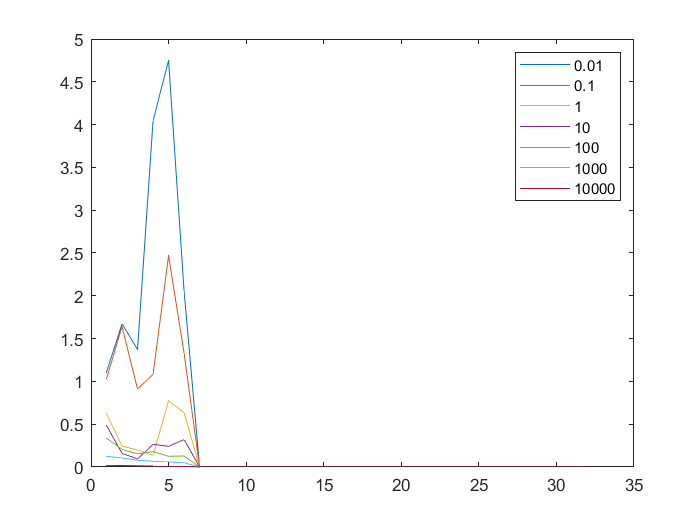

%Q3a
alpha2=0.01;
iterations=10;
for j=1:7
for runs =1: iterations

    alpha1(j)=alpha2;
    data=randi([0 3],n_ele,1);
    Sym = QPSKModulator(data)*sqrt(2);
    X3=diag(Sym);
    X3(1:180,1:180)=0;
    X3(end-179:end,end-179:end)=0;
    H3=X3*F;
    nr=mvnrnd(zeros(n_ele,1),.01);%variance {0.1,0.01}
    ni=mvnrnd(zeros(n_ele,1),.01);
    n=nr+1i*ni;
H3a=X3*F;
y3a(:,j)=H3a*h + n;
H2=H3a(:,NonZeros);
h_hat_inv3a=inv(H2'*H2+alpha2*eye(6,6))*H2'*y3a(:,j);
h_hat_est3a=zeros(size(h));
h_hat_est3a(NonZeros,:)=h_hat_inv3a;
Jmin3b(j,runs)=norm(y3a(:,j)-H2*h_hat_inv3a).^2;

h_hat_est_3a_mat(:,j,runs)=h_hat_est3a;

end
h_hat_mean = mean(h_hat_est_3a_mat,3);
plot(abs(h_hat_mean));
alpha2=alpha2*10;
end
alpha_val=string(alpha1);
legend(alpha_val);

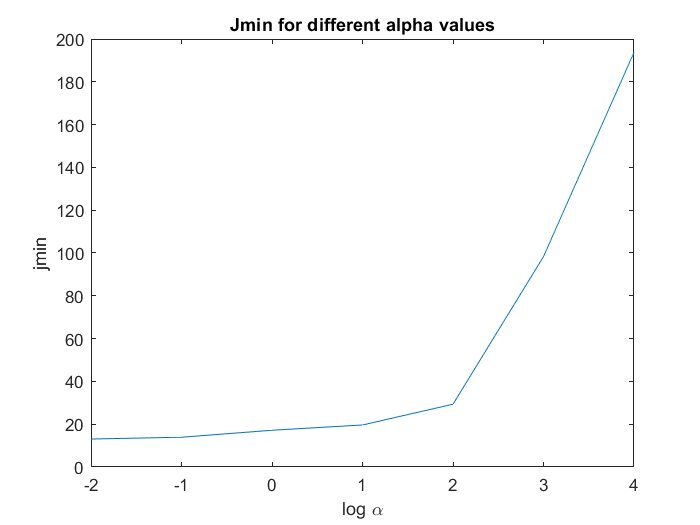

figure;
plot(log10(alpha1),mean(Jmin3b,2));ylabel('jmin');xlabel('log \alpha')
title('Jmin for different alpha values')



for i = 1:length(alpha1)
    hh = h_hat_mean(:,i);
    MSE_sim(i)= norm(h-hh).^2;
end
MSE_sim%MSE of different alpha

MSE_sim =    49.2377   13.2917    1.6546    0.6458    0.4147    0.5335    0.6698


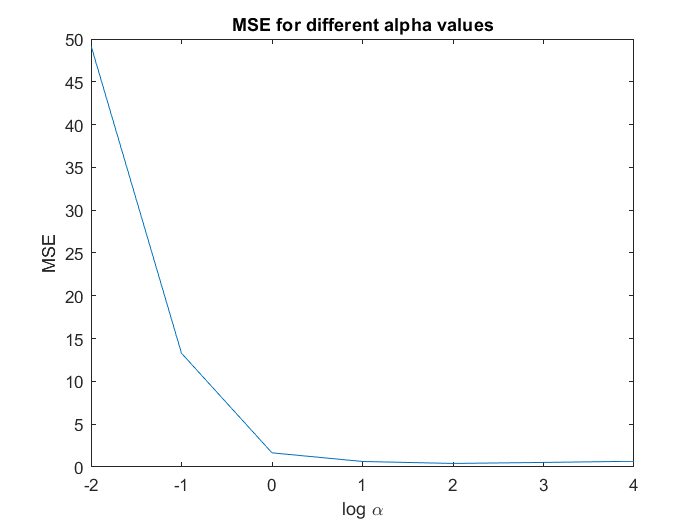

figure;
plot(log10(alpha1),MSE_sim);
ylabel('MSE');xlabel('log \alpha')
title('MSE for different alpha values')

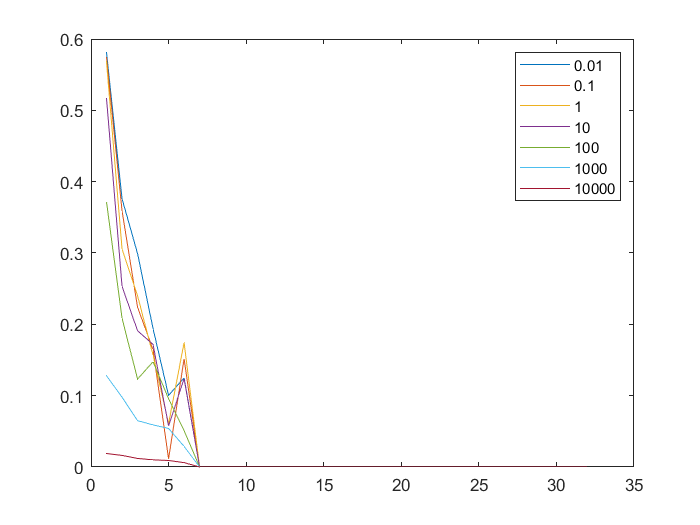


%Q3b

alpha2=0.01;
iterations=10;
for j=1:7
for runs =1: iterations

    alpha1(j)=alpha2;
    data=randi([0 3],n_ele,1);
    Sym = QPSKModulator(data)*sqrt(2);
    X3=diag(Sym);
    X3(1:180,1:180)=0;
    X3(end-179:end,end-179:end)=0;
    H3=X3*F;
    nr=mvnrnd(zeros(n_ele,1),.01);%variance {0.1,0.01}
    ni=mvnrnd(zeros(n_ele,1),.01);
    n=nr+1i*ni;
H3b=X3*F;
y3b(:,j)=H3b*h2 + n;
H2=H3b(:,NonZeros);
h_hat_inv3b=inv(H2'*H2+alpha2*eye(6,6))*H2'*y3b(:,j);
h_hat_est3b=zeros(size(h));
h_hat_est3b(NonZeros,:)=h_hat_inv3b;
Jmin3b(j,runs)=norm(y3b(:,j)-H2*h_hat_inv3b).^2;

h_hat_est_3b_mat(:,j,runs)=h_hat_est3b;

end
h_hat_mean = mean(h_hat_est_3b_mat,3);
plot(abs(h_hat_mean));
alpha2=alpha2*10;
end
alpha_val=string(alpha1);
legend(alpha_val);

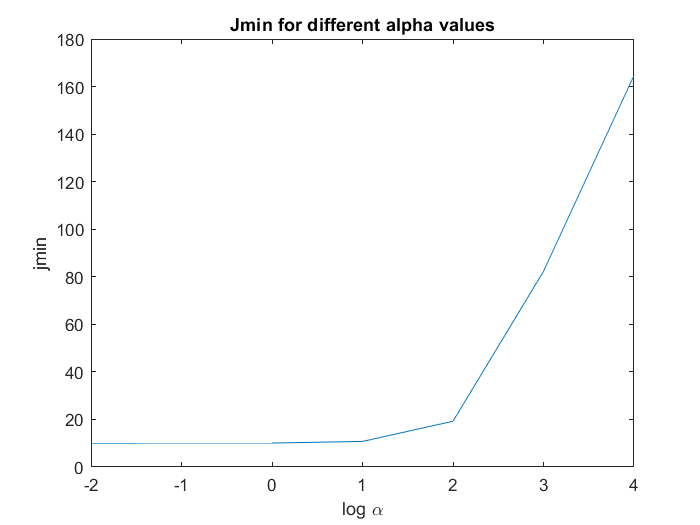

figure;
plot(log10(alpha1),mean(Jmin3b,2));ylabel('jmin');xlabel('log \alpha')
title('Jmin for different alpha values')



for i = 1:length(alpha1)
    hh = h_hat_mean(:,i);
    MSE_sim(i)= norm(h2-hh).^2;
end
MSE_sim%MSE of different alpha

MSE_sim =     0.0835    0.0256    0.0577    0.1042    0.2174    0.4392    0.5893


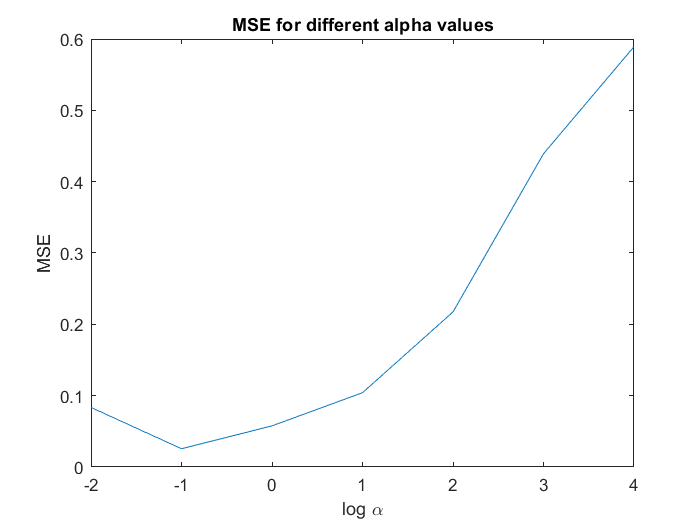

figure;
plot(log10(alpha1),MSE_sim);
ylabel('MSE');xlabel('log \alpha')
title('MSE for different alpha values')